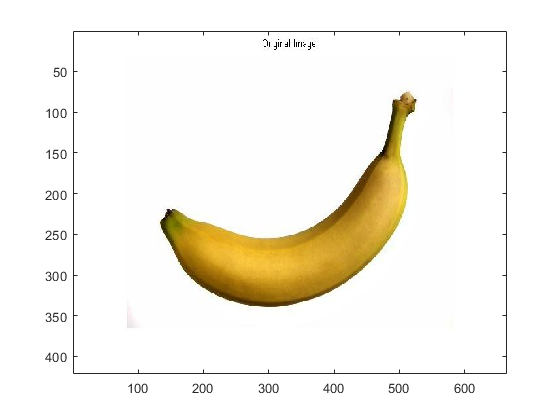

% Firstly, We are reading in the image
A = imread('banana_fruit.jpg');
image(A)


% Get the filter

h_gaussian = fspecial('gaussian'); % Defining the Gaussian Filter
h_average = fspecial('average'); % Defining an averaging filter


% Perform filtering
B_gaussian = imfilter(A, h_gaussian);
B_average = imfilter(A, h_average);

% Converting the image to a Gray scale Image
B = rgb2gray(A)

B = 421×664 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255

med = medfilt2(B) % Seeing the Median filter

med = 421×664 uint8 matrix
     0   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   2

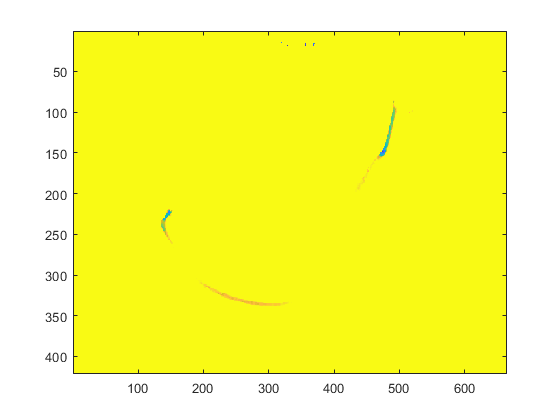

image(med)

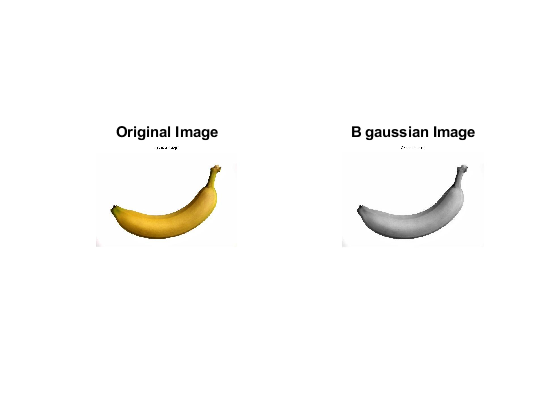

% Plotting the Images using subplots
figure, subplot(1,2,1), imshow(A), title('Original Image');
subplot(1,2,2), imshow(B), title('B gaussian Image');

Now we will be converting this image into a Binary Image

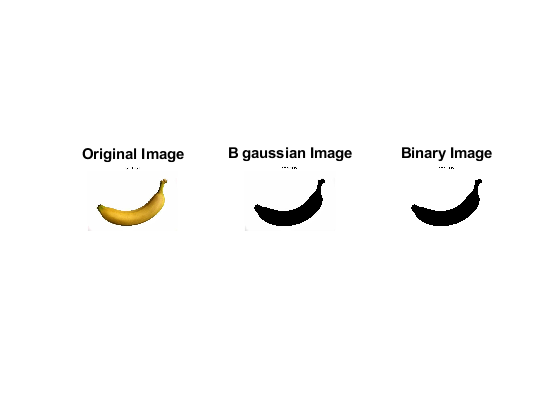

B(B<225) = 0; % Setting the threshold
% Converting to binary Image
% C = imbinarize(B);
figure, subplot(1,3,1), imshow(A), title('Original Image');
subplot(1,3,2), imshow(B), title('B gaussian Image');
subplot(1,3,3), imshow(C), title('Binary Image');

Erosion & Dilation

s = strel('disk',15,8) % Defining Structuring Element

s = strel is a disk shaped structuring element with properties:

      Neighborhood: [29×29 logical]
    Dimensionality: 2


## EROSION

E = imerode(C,s) % Eroding the Image by structuring element

E = 421×664 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

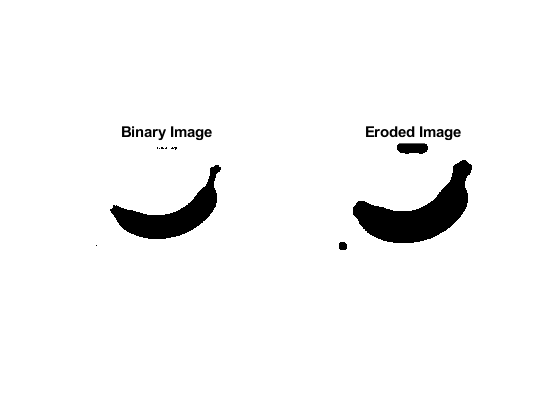

%Plotting
figure, subplot(1,2,1), imshow(C), title('Binary Image')
subplot(1,2,2), imshow(E), title('Eroded Image')

## DILATION

D = imdilate(C,s)  % Dilating the Image by structuring element

D = 421×664 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

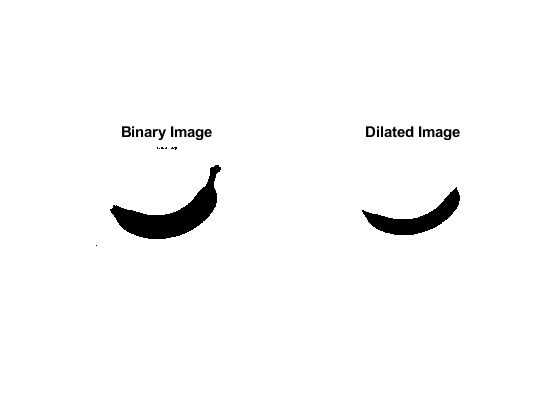

% Plotting
figure, subplot(1,2,1), imshow(C), title('Binary Image')
subplot(1,2,2), imshow(D), title('Dilated Image')